UNIVERSIDADE FEDERAL DE VIÇOSA

ELT - 410 SINAIS E SISTEMAS

Gabriel Pereira de Calais e Márcio Von Rondow Campos

clc; clear all; close all;

Roteiro Prática 8

### Carregando Imagens

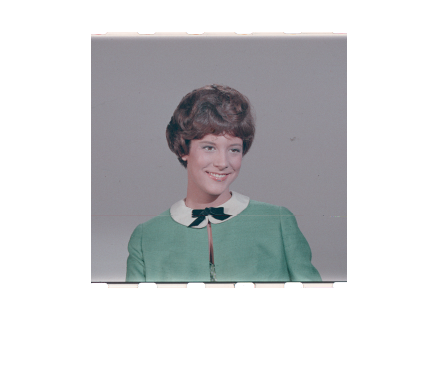

ima = imread('4.1.03.tiff'); %Carrega a imagem para a workspace
figure;
imshow(ima, []); %Plota a imagem em uma figura

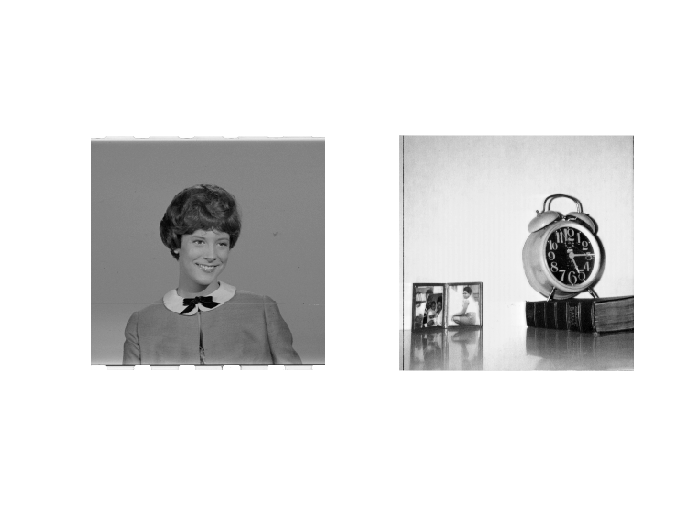

ima = rgb2gray(ima);

figure;
subplot(1,2,1) 
imshow(ima, [])
imb = imread('5.1.12.tiff'); %Carrega a imagem para a workspace
subplot(1,2,2)
imshow(imb, []); %Plota a imagem em uma figura

### Tranformada no Módulo e Fase

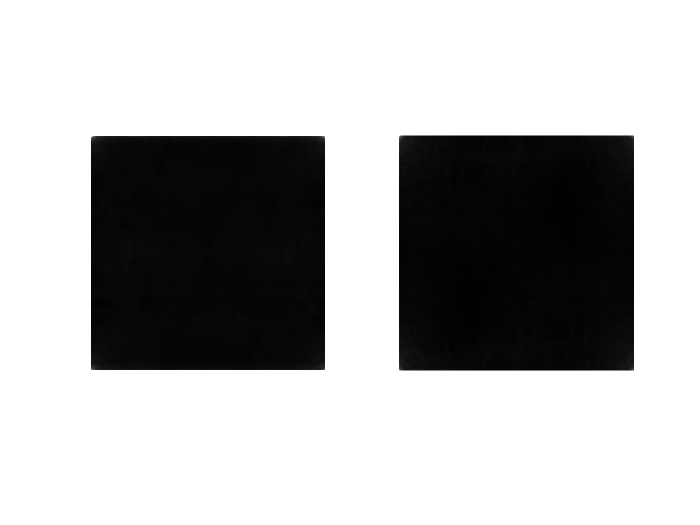

IMa = fft2(ima); %Realiza a tranformada de Fourier 2D da imagem
IMb = fft2(imb); %Realiza a tranformada de Fourier 2D da imagem

ima1 = real(ifft2(abs(IMa))); %Realiza a tranformada inversa de Fourier 2D do módulo da imagem
imb1 = real(ifft2(abs(IMb))); %Realiza a tranformada inversa de Fourier 2D do módulo da imagem

figure; 
subplot(1,2,1);
imshow(ima1, []); %Plota a imagem em uma figura
subplot(1,2,2);
imshow(imb1, []); %Plota a imagem em uma figura

### Transformada Inversa no Módulo e Fase

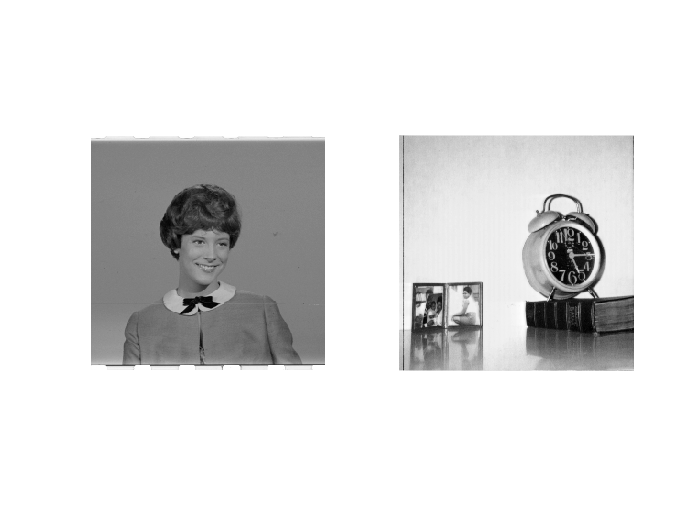

ima3 = real(ifft2(abs(IMa).*exp(1i*angle(IMa)))); %Realiza a tranformada inversa de módulo e fase da imagem
imb3 = real(ifft2(abs(IMb).*exp(1i*angle(IMb)))); %Realiza a tranformada inversa de módulo e fase da imagem

figure; 
subplot(1,2,1);
imshow(ima3, []); %Plota a imagem em uma figura
subplot(1,2,2)
imshow(imb3, []); %Plota a imagem em uma figura

### Transformada na Fase

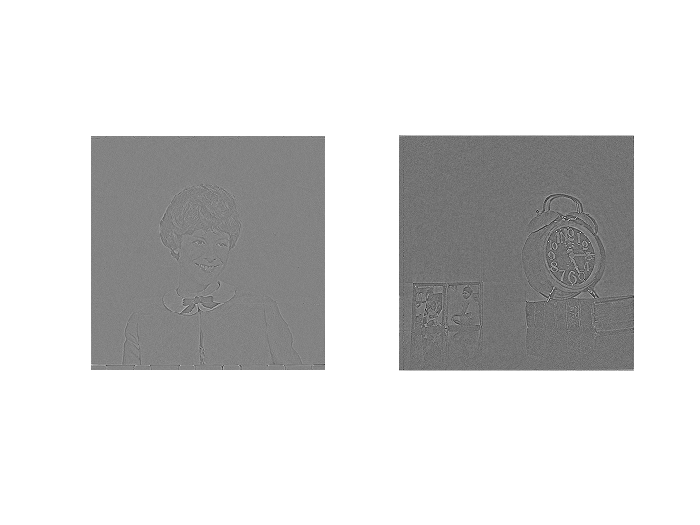

ima2 = real(ifft2(exp(1i*angle(IMa)))); %Realiza a tranformada inversa de Fourier 2D da fase da imagem
imb2 = real(ifft2(exp(1i*angle(IMb)))); %Realiza a tranformada inversa de Fourier 2D da fase da imagem

figure; 
subplot(1,2,1);
imshow(ima2, []); %Plota a imagem em uma figura
subplot(1,2,2)
imshow(imb2, []); %Plota a imagem em uma figura

### Transformada no Módulo

ima3 = real(ifft2(abs(IMa))); %Realiza a tranformada de módulo da imagem
imb3 = real(ifft2(abs(IMb))); %Realiza a tranformada de módulo da imagem

figure; 
subplot(1,2,1);
imshow(ima3, []); %Plota a imagem em uma figura
subplot(1,2,2)
imshow(imb3, []); %Plota a imagem em uma figura

### Transformada Módulo de uma e Fase da Outra

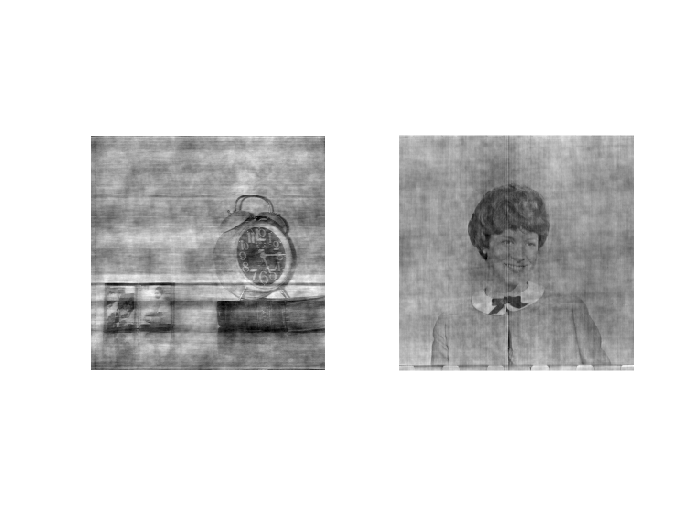

imab = real(ifft2(abs(IMa).*exp(1i*angle(IMb)))); %Realiza a tranformada inversa de módulo e fase da imagem
figure; 
subplot(1,2,1);
imshow(imab, []);
imba = real(ifft2(abs(IMb).*exp(1i*angle(IMa)))); %Realiza a tranformada inversa de módulo e fase da imagem
subplot(1,2,2);
imshow(imba, []);